# Diffraction by a Straight Edge

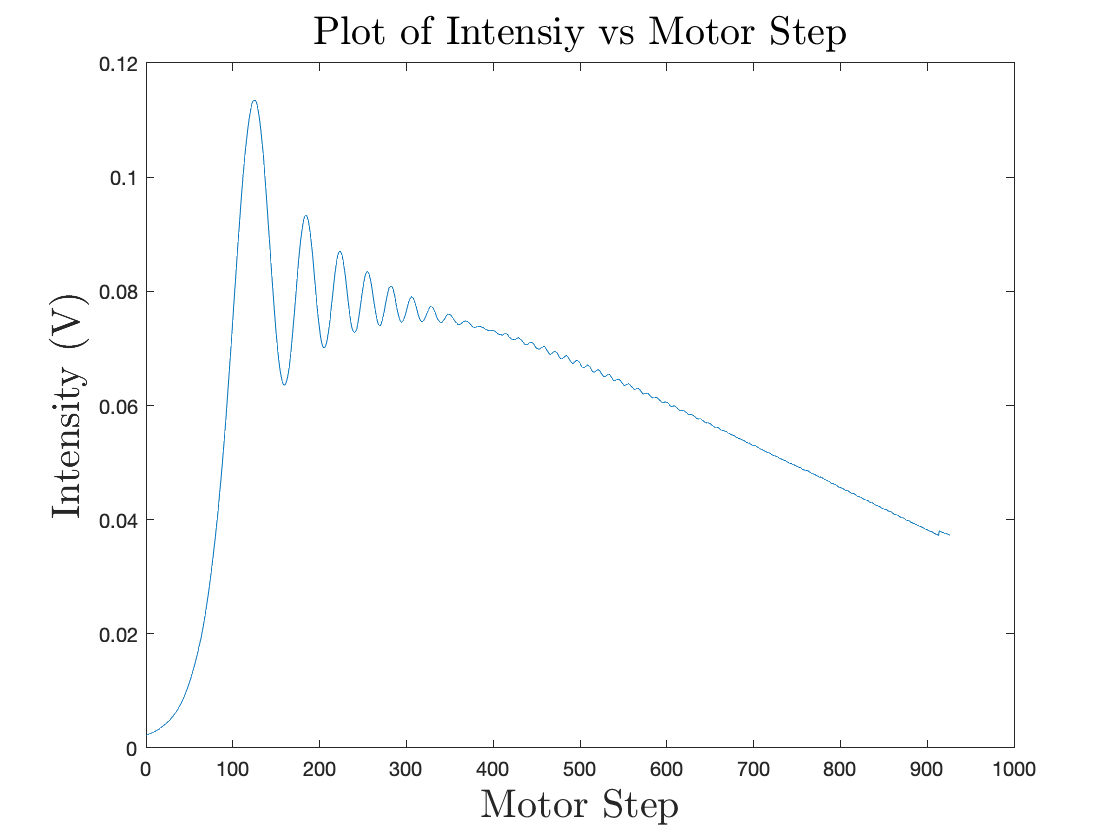

% Get motop step in units of meters 
% so x_max, x_min can be in units of meters
steps_per_rev = 400; 
dist_per_rev = 0.00508; % meters of travel
step_size = dist_per_rev/steps_per_rev;

fontsize = 20;
% Get locations of peaks from intensity data
v = dlmread('Laser_lab_data.csv',',',1,0);
v = -1.*v(50:end,:);
step_stop = step_size*length(v);
x_distance = linspace(0,step_stop,length(v))';

x_end = length(v)-1;
x_numpoints = length(v);
x = linspace(0, x_end, x_numpoints)';
plot(x, v)
title('Plot of Intensiy vs Motor Step',...
    'FontSize',fontsize,'Interpreter','latex')
xlabel("Motor Step",...
    'FontSize',fontsize,'Interpreter','latex')
ylabel("Intensity (V)",...
    'FontSize',fontsize,'Interpreter','latex')

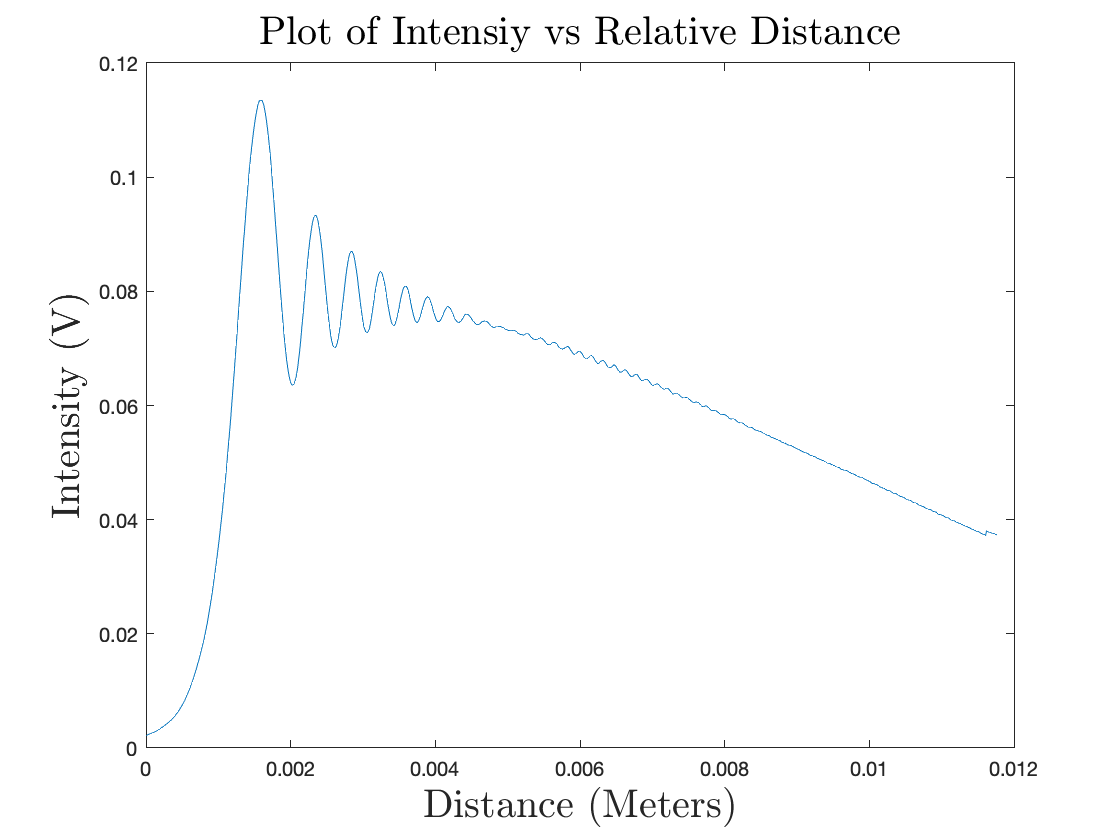


plot(x_distance, v)
title('Plot of Intensiy vs Relative Distance',...
    'FontSize',fontsize,'Interpreter','latex')
xlabel("Distance (Meters)",...
    'FontSize',fontsize,'Interpreter','latex')
ylabel("Intensity (V)",...
    'FontSize',fontsize,'Interpreter','latex')

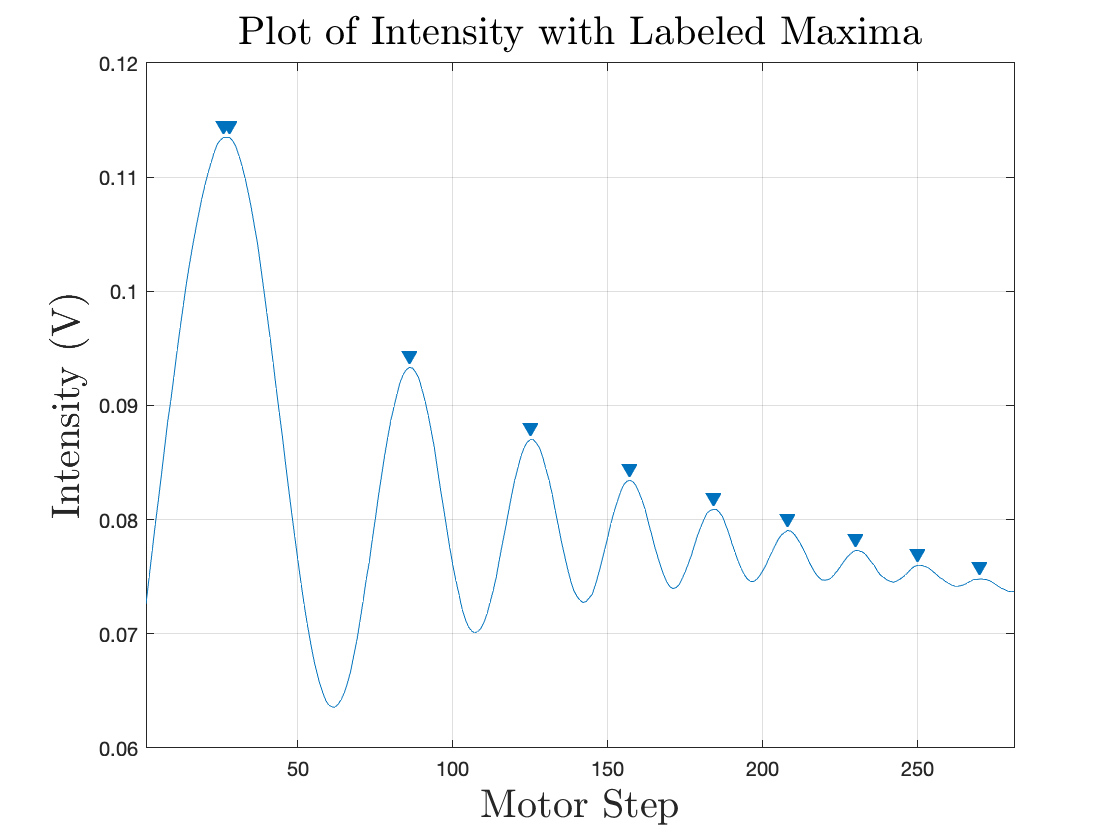


% Maxima
findpeaks(v(100:380,:))
title('Plot of Intensity with Labeled Maxima',...
    'FontSize',fontsize,'Interpreter','latex')
xlabel("Motor Step",...
    'FontSize',fontsize,'Interpreter','latex')
ylabel("Intensity (V)",...
    'FontSize',fontsize,'Interpreter','latex')

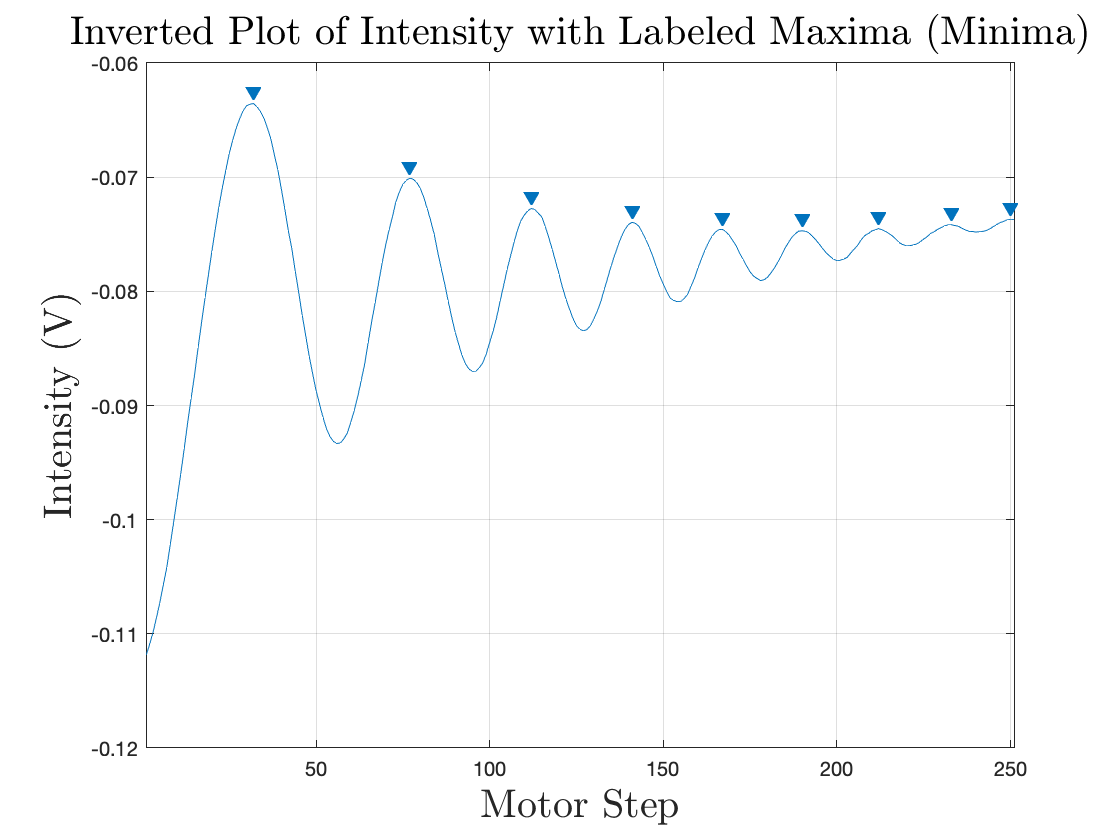

[vals_max, x_max] = findpeaks(v(100:380,:));
x_max = x_max(2:end,:);

% Minima
findpeaks(-1.*v(130:380,:));
title(['Inverted Plot of Intensity with ' ...
    'Labeled Maxima (Minima)'],...
    'FontSize',fontsize,'Interpreter','latex')
xlabel("Motor Step",...
    'FontSize',fontsize,'Interpreter','latex')
ylabel("Intensity (V)",...
    'FontSize',fontsize,'Interpreter','latex')

[vals_min, x_min] = findpeaks(-1.*v(130:380,:));
x_min = x_min(1:end,:);

save('max_locations.mat', 'x_max')
save('min_locations.mat', 'x_min')


a) When performing the LSQ fit of *x**m *vs. *G(m,k)*, what *σ**xm *was required to obtain a  *v*2 around 1? More specifically, how many steps of the stepper motor does this *σ**xm *correspond to and what do you expect it to be? 

b) Derive an equation for *λ *and *σ* (*σ**s*, *σ**L*, *σ**y *) from equation 3.8 and also give a numerical value for *λ *and *σ* (*σ**s*, *σ**L*, *σ**y *) based on your fit results from part a). Specify the values for *σ**L *and *σ**y *used in your calculations. 

c) The wavelength of a typical He-Ne laser is 632.8 nm. How many sigmas is the result you obtained in part b) off from this accepted value? Calculate (or look up) what the probability of such an event is for a Normal, i.e., Gaussian, distribution. 

d) If the result in part c) was more than 3 sigmas off, how much would the values for *σ**L *and *σ**y *have to be adjust to get a reasonable value, i.e., 1 to 2 sigmas? 

### 
$$x_{m}=\sqrt{\lambda} F(L, y) G(m, k)$$


### 
$$F(L, y)=\sqrt{\frac{L(L-y)}{2 y}}$$
       
$$G(m, k)=\sqrt{(4 m+k)}$$
       

Our goal is to get the lambda from the slope of  

### $x_{m} = Gs+x_{0}$       where

### 
$$s = F(L,y) \sqrt(\lambda)$$
 

We're fitting x_m vs G, so the term  F*sqrt(lambda) is our slope (s)

### 
$$\lambda = \frac{s^{2} y}{L\left(\frac{L}{2}-\frac{y}{2}\right)}$$


### 
$$\sigma_{\lambda} = \sqrt{\sigma_{L}^2\left(\frac{\partial \lambda}{\partial L}\right)^2 + \sigma_{s}^2\left(\frac{\partial \lambda}{\partial s}\right)^2 + \sigma_{y}^2\left(\frac{\partial \lambda}{\partial y}\right)^2}$$


### 
$$\sigma_{\lambda} = 2 \sqrt{\frac{s^{4} \sigma_{y}^{2}}{(L-y)^{4}}+\frac{4 s^{2} \sigma_{s}^{2} y^{2}}{L^{2}(L-y)^{2}}+\frac{s^{4} \sigma_{L}^{2} y^{2}(2 L-y)^{2}}{L^{4}(L-y)^{4}}}$$


syms F G L y m k lambda x_m x_0 s
assume(y>0), assume(L>0), assume(m>0), assume(x_m>0)
assume(F>0), assume(G>0), assume(s>0), assume(lambda>0)
x_m = sqrt(lambda)*F*G;
x_m = x_m+x_0; % MAIN EQUATION
equ = x_m == subs(x_m, sqrt(lambda)*F, s);
x_m = subs(x_m, sqrt(lambda)*F, s);
lambda = solve(equ, lambda);
lambda = subs(lambda,F,sqrt((L*(L-y))/(2*y)));
syms DlambdaDs sigma_s DlambdaDL sigma_L DlambdaDy sigma_y
DlambdaDs = simplify(diff(lambda, s));
DlambdaDL = simplify(diff(lambda, L));
DlambdaDy = simplify(diff(lambda, y));
sigma_lambda = sqrt(sigma_s^2*(DlambdaDs)^2+...
                    sigma_L^2*(DlambdaDL)^2+...
                    sigma_y^2*(DlambdaDy)^2)

$$sigma\_lambda = 2\,\sqrt{\frac{s^{4}\,{\sigma_{y}}^{2}}{{\left(L-y\right)}^{4}}+\frac{4\,s^{2}\,{\sigma_{s}}^{2}\,y^{2}}{L^{2}\,{\left(L-y\right)}^{2}}+\frac{s^{4}\,{\sigma_{L}}^{2}\,y^{2}\,{\left(2\,L-y\right)}^{2}}{L^{4}\,{\left(L-y\right)}^{4}}}$$